# Plot multipoles for a given symmetry group

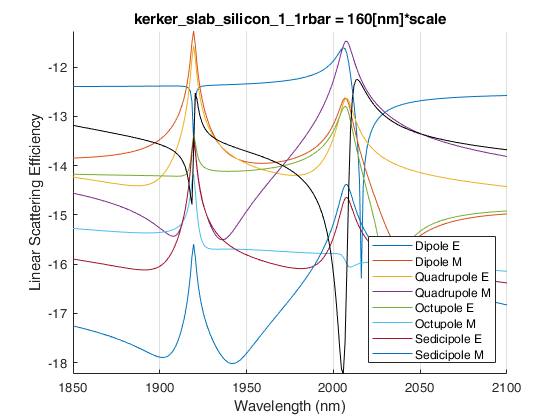

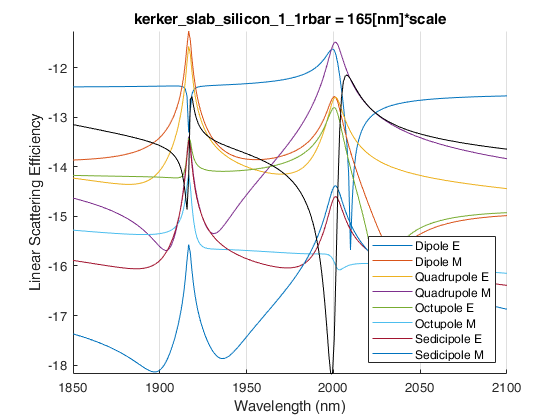

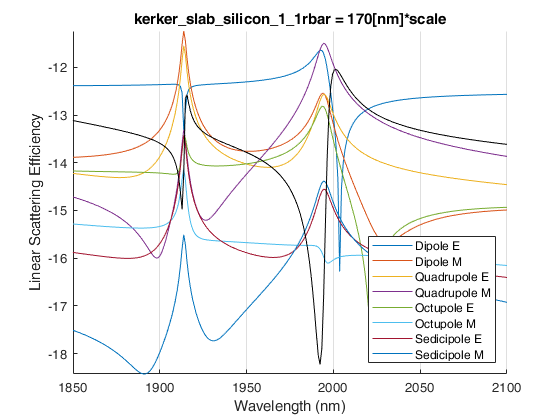

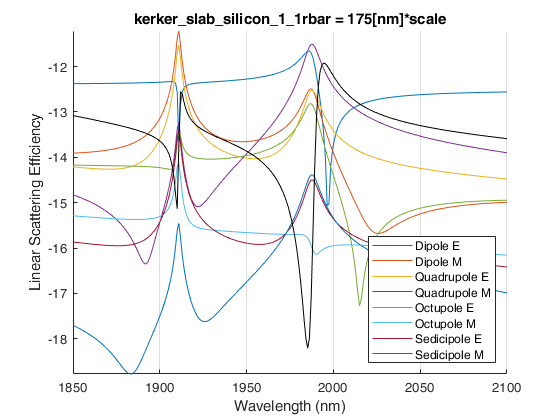

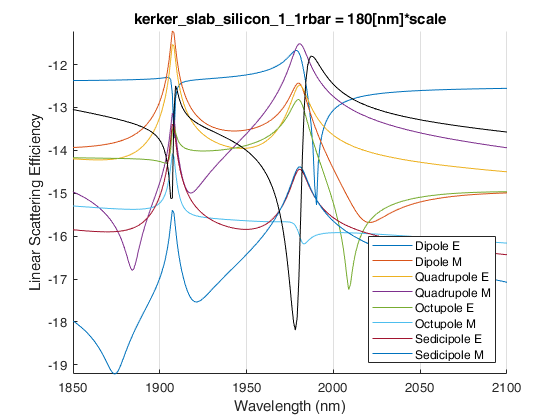

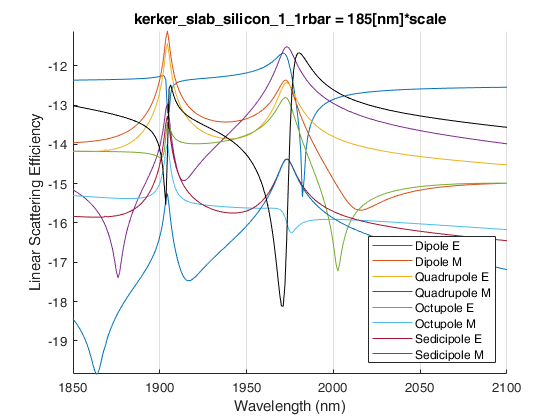

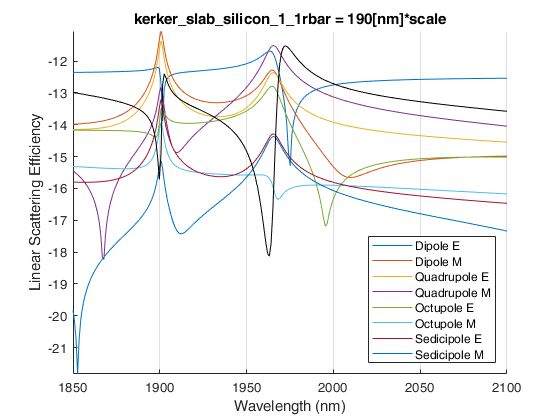

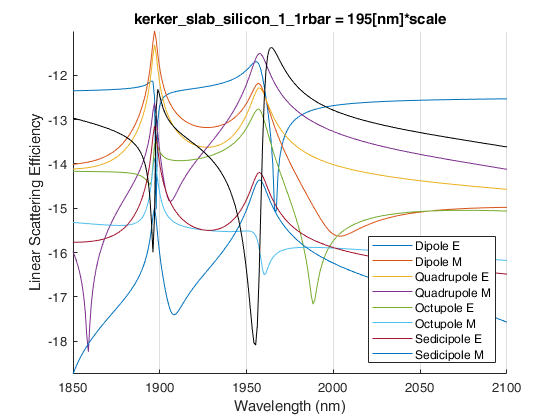

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config\sweeps');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed');

symmetry_group = Mie;

for job = "kerker_slab_silicon_1_1"
    eval(job);
    load([options.output_dir_final 'sweep_data.mat']);
    extra_options = matthew_extra_options(options);
    
    for study_num = 1:height(sweep_data)
        derived_values = sweep_data(study_num,:).DerivedValues{1};
        wlengths = (299792458./derived_values.signal.freq)';

        
        fig = figure;
        hold on;
        %yyaxis left;
        
        for mpole = [symmetry_group.modes]
            switch mpole.mode.parity
                case "even" 
                    results = derived_values.signal_mpole_even.l_e == mpole.mode.l &...
                        derived_values.signal_mpole_even.m_e == mpole.mode.m;
                    plot(wlengths, log10(derived_values.signal_mpole_even.CscaEe(results)));
                    results = derived_values.signal_mpole_even.l_e == mpole.mode.l &...
                        derived_values.signal_mpole_even.m_e == mpole.mode.m;
                    plot(wlengths, log10(derived_values.signal_mpole_even.CscaMe(results)));
                case "odd" 
                    results = derived_values.signal_mpole_odd.l_o == mpole.mode.l &...
                        derived_values.signal_mpole_odd.m_o == mpole.mode.m;
                    plot(wlengths, log10(derived_values.signal_mpole_odd.CscaEo(results)));
                    results = derived_values.signal_mpole_odd.l_o == mpole.mode.l &...
                        derived_values.signal_mpole_odd.m_o == mpole.mode.m;
                    plot(wlengths, log10(derived_values.signal_mpole_odd.CscaMo(results)));
                case "mie" 
                    results = derived_values.signal_mpole_mie.l == mpole.mode.l;
                    plot(wlengths, log10(derived_values.signal_mpole_mie.CscaE(results)));
                    results = derived_values.signal_mpole_mie.l == mpole.mode.l;
                    plot(wlengths, log10(derived_values.signal_mpole_mie.CscaM(results)));
                otherwise
                    error("Unknown multipole type");
            end
        end
        
        ylabel('Linear Scattering Efficiency');
        xlabel('Wavelength (nm)');
        %{
        yyaxis right;
        plot(wlengths, derived_values.signal.scat_eff);
        plot(wlengths, derived_values.signal.sigma_scup/derived_values.signal.surface_area(1));
        plot(wlengths, derived_values.signal.sigma_scdn/derived_values.signal.surface_area(1));
        %axis([wlengths(end) wlengths(1) 0.5 8]);
        leg_scat3 = legend([symmetry_group.legend, 'Scattering Efficiency', 'up', 'down']);
        %}
        plot(wlengths, derived_values.signal.scat_eff-19, 'k');
        leg_scat3 = legend(symmetry_group.legend);
        leg_scat3.Location = 'southeast';
        set(gca, 'YGrid', 'off', 'XGrid', 'on');
        title(strcat(job, "rbar = ",sweep_data(study_num,:).r_bar), 'Interpreter', 'none');
        axis tight;
        %saveas(fig, strcat("C:\Users\Matthew\Downloads\",job), 'png');
    end
end

   function out = Mie()
        out.legend = {'Dipole E','Dipole M', 'Quadrupole E','Quadrupole M','Octupole E',...
            'Octupole M','Sedicipole E','Sedicipole M'};
        out.modes(4).mode.l = 4;
        out.modes(4).mode.m = 1;
        out.modes(4).mode.parity = "mie";
        out.modes(3).mode.l = 3;
        out.modes(3).mode.m = 1;
        out.modes(3).mode.parity = "mie";
        out.modes(2).mode.l = 2;
        out.modes(2).mode.m = 1;
        out.modes(2).mode.parity = "mie";
        out.modes(1).mode.l = 1;
        out.modes(1).mode.m = 1;
        out.modes(1).mode.parity = "mie";
        
   end
   function out = D2h()
        out.legend = {'l=1,m=1','l=2,m=0'};
        out.modes(2).mode.l = 2;
        out.modes(2).mode.m = 0;
        out.modes(2).mode.parity = "even";
        out.modes(1).mode.l = 1;
        out.modes(1).mode.m = 1;
        out.modes(1).mode.parity = "odd";
        
    end
